## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:130, 133];
%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:131, 133, 141:142]; 
%cfg.subNums = [101:103, 105:106, 108:113, 115:117, 119:120, 122, 124, 128:131, 133, 141:142]; 
cfg.subNums = [101:103, 105:106, 108:113, 115:117, 119:120, 122, 124, 128:131, 133]; 
cfg.FontSize = 20;
cfg = defaultCfg(cfg);

% Also did MRI but have different electrode placement 
%121
%126
%114
%127



### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preprocess_EEG(cfg);

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

 In ft_defaults>checkMultipleToolbox at line 430
 In ft_defaults at line 235



Pre-processed data for sub-101 exist already

Pre-processed data for sub-102 exist already

Pre-processed data for sub-103 exist already

Pre-processed data for sub-105 exist already

Pre-processed data for sub-106 exist already

Pre-processed data for sub-108 exist already

Pre-processed data for sub-109 exist already

Pre-processed data for sub-110 exist already

Pre-processed data for sub-111 exist already

Pre-processed data for sub-112 exist already

Pre-processed data for sub-113 exist already

Pre-processed data for sub-115 exist already

Pre-processed data for sub-116 exist already

Pre-processed data for sub-117 exist already

Pre-processed data for sub-119 exist already

Pre-processed data for sub-120 exist already

Pre-processed data for sub-122 exist already

Pre-processed data for sub-124 exist already

Pre-processed data for sub-128 exist already

Pre-processed data for sub-129 exist already

Pre-processed data for sub-130 exist already

Pre-processed data for sub-131 exi


% tfa
runTFA_bandwise(cfg)

### Category decoding

disp(['Running decoding...' newline]);

Running decoding...



% decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);

Running individual decoding...



% individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = false;
cfg.plot_rdm = false;
cfg.pca = true;
cfg.nTrials2average = 1;
cfg.frequencies = {'full', 'alpha', 'beta', 'gamma'};
%cfg.frequencies = {'full'};
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



[d.pairRep, d.meanAcc, cfg] = PairwiseTPLDAclassifier(cfg);

Loading pairwise decoding for subject sub-101
Loading pairwise decoding for subject sub-102
Loading pairwise decoding for subject sub-103
Loading pairwise decoding for subject sub-105
Loading pairwise decoding for subject sub-106
Loading pairwise decoding for subject sub-108
Loading pairwise decoding for subject sub-109
Loading pairwise decoding for subject sub-110
Loading pairwise decoding for subject sub-111
Loading pairwise decoding for subject sub-112
Loading pairwise decoding for subject sub-113
Loading pairwise decoding for subject sub-115
Loading pairwise decoding for subject sub-116
Loading pairwise decoding for subject sub-117
Loading pairwise decoding for subject sub-119
Loading pairwise decoding for subject sub-120
Loading pairwise decoding for subject sub-122
Loading pairwise decoding for subject sub-124
Loading pairwise decoding for subject sub-128
Loading pairwise decoding for subject sub-129
Loading pairwise decoding for subject sub-130
Loading pairwise decoding for subj


% stats and plotting
disp(['Running t-test on pairwise decoding accuracies...' newline]);

Running t-test on pairwise decoding accuracies...



d.stats.pairDec = plot_decoding_results(cfg, d);

### ISC of representation

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.smoothing_window = 5;
cfg.regressOutMean = false;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
cfg.plot_sem = false;

% do permutation test
cfg.permutationtest = false;
cfg.n_permutations = 10000;

disp(['Running ISC...' newline]);

Running ISC...



[d, d.stats.ISC] = getISCofRespresentation(cfg,d);

### ISC of representation with regressOutMean

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
cfg.new_figure = false;
cfg.permutationtest = false;
disp(['Running ISC...' newline]);

Running ISC...



[d, ~] = getISCofRespresentation(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
%cfg.layer_type = 'early_mid';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = false;
cfg.MaxColorValue = 1;
cfg.new_figure = true;

% Create output directory if wanted
% output_dir = fullfile(pwd, '..', 'dnn_features');
% if exist(output_dir, 'dir')
%     rmdir(output_dir, 's');
% end

% get images
cfg.analysis_names = {'typical', 'control', 'photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded image: 111_bat_gen3.png
Loaded image: 112_bat_gen1.png
Loaded image: 112_bat_gen2.png
Loaded i


% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg); % in the function cfg.regressOutMean = false!

analysis typical - layer #1 - category: bathroom
analysis control - layer #1 - category: bathroom
analysis photos - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen
analysis control - layer #1 - category: kitchen
analysis photos - layer #1 - category: kitchen



% filter for included subjects
d = filterCurrentSubs(d, cfg);

### Compare ISC from drawings with ISC of neural representations 

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.regressOutMean = true;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
%cfg.predictor_RDMs = {'typical_early', 'control_early', 'photos_early'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.correlation_type = 'Pearson';
cfg.smoothing_window = 5;
cfg.ISC_type = 'pISC';

% run
%d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

% get stats
cfg.n_permutations = 5000;
cfg.min_cluster_size = 2;

[d.stats.ISC_RSA, d.r_vals.ISC_RSA] = compare_to_drawings_tp(cfg, d)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


TP 140 out of 140 - bathroom - full
TP 140 out of 140 - kitchen - full
TP 30 out of 36 - bathroom - alpha
TP 30 out of 36 - kitchen - alpha
TP 30 out of 36 - bathroom - beta
TP 30 out of 36 - kitchen - beta
TP 30 out of 36 - bathroom - gamma
TP 30 out of 36 - kitchen - gamma


d = struct with fields:
    pairRep: [1×1 struct]
    meanAcc: [1×1 struct]
      stats: [1×1 struct]
        ISC: [1×1 struct]
        DNN: [1×1 struct]
     r_vals: [1×1 struct]
       pISC: [1×1 struct]


d = struct with fields:
    pairRep: [1×1 struct]
    meanAcc: [1×1 struct]
      stats: [1×1 struct]
        ISC: [1×1 struct]
        DNN: [1×1 struct]
     r_vals: [1×1 struct]
       pISC: [1×1 struct]


%[d.stats.ISC_RSA, d.r_vals.ISC_RSA]  = compare_to_drawings_frq_bands(cfg, d);

% plotting
cfg.p_type = 'cluster_p' % p_vals, cluster_p, or fdr_p

cfg = struct with fields:
             functionPath: 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_eeg\code\utilities'
                  subNums: [101 102 103 105 106 108 109 110 111 112 113 115 116 117 119 120 122 124 128 129 130 131 133]
                 FontSize: 20
                        n: 23
               categories: {'bathroom'  'kitchen'}
                  exp_num: 1
                  nTrials: 100
                  nBlocks: 20
              trialLength: 0.2500
                ISC_types: {'pairRep'}
                      dnn: 'vgg16_imagenet'
           analysis_names: {'typical'  'control'  'photos'}
                 plotting: 1
                   saving: 1
            dissimilarity: 1
               classifier: @cosmo_classify_lda
           sourcedataPath: 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_eeg\code\..\sourcedata'
               outputPath: 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Un

Unrecognized field name "alpha".

Error in plot_corr_sig (line 32)
    timepoints = d.pairRep.(frqBand).included_time;

cfg.plotting = true;
cfg.ylim = [-0.1, 0.1];
plot_corr_sig(cfg, d);

### Behavioral data

Out of 2 tests, 2 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
Out of 25 tests, 25 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.
All  subjects are significant better then chance level.


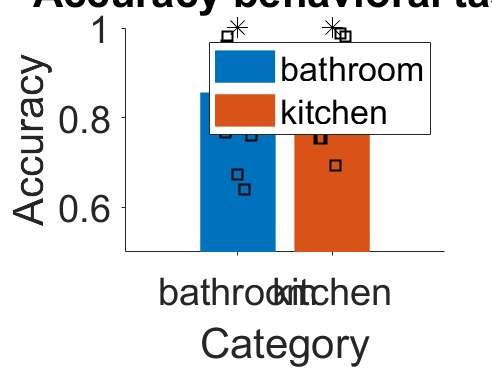

d.beh = beh_task(cfg);

### Stimuli RDM

cfg.dnns = {'vgg16_imagenet'};
% cfg.layer_type = 'late';
cfg.layer_type = 'early_mid_late';
cfg.correlation_type = 'Spearman';
cfg.partial_cor = false;
cfg.dissimilarity = true;
cfg.plot_rdm = false;
cfg.new_figure = true;
cfg.analysis_names = {'stimuli'};
cfg.exp_num = 2;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features', 'stimuli');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

if ~exist('images','var')
    images = struct;
end

cfg.predictor_RDMs = {'stimuli_early', 'stimuli_intermediate', 'stimuli_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
[cfg, d, images] = make_RDM_for_stimuli(cfg, d, images);

Loaded image: labelme_sfxiulhjbhlyiyt.tif
Loaded image: sun_aapitsgbtktqubfy.tif
Loaded image: sun_aavhrsfjbserjtht.tif
Loaded image: sun_abapwbhyhkfixyex.tif
Loaded image: sun_abjtwfukuwddzted.tif
Loaded image: sun_acduarbnmmoglmiv.tif
Loaded image: sun_acegryoqftbzowsg.tif
Loaded image: sun_acgyywnybuveqsro.tif
Loaded image: sun_aclfzgynxzxlbepz.tif
Loaded image: sun_afcoljnjfoxjtgja.tif
Loaded image: sun_aggnnqpdorgxpvce.tif
Loaded image: sun_agguqiubmwhqqunb.tif
Loaded image: sun_aghyqhbptboemmoq.tif
Loaded image: sun_agrwbmhcpmfuwmsg.tif
Loaded image: sun_agyqfjcfkdcydepw.tif
Loaded image: sun_ahaulkltgpkeeemi.tif
Loaded image: sun_ahcvzmoyaycdoftf.tif
Loaded image: sun_ahijqszoswveeyji.tif
Loaded image: sun_ahqjwnzgolcaoidx.tif
Loaded image: sun_ajlawzvmubibwbpy.tif
Loaded image: sun_akiytfaagpdsphgz.tif
Loaded image: sun_aleqenyvunhactkl.tif
Loaded image: sun_aljolscmmzydegqp.tif
Loaded image: sun_alkosphxlxwjwgjd.tif
Loaded image: sun_alotolagknyrgtsk.tif
Loaded image: sun_ambr

### Compare stimuli RDM with pairwise decoding

cfg.save_name = 'compare_tp_RDMs_to_stimuli_RDM'
cfg.dissimilarity = false;
d.stimuli = compare_pairwiseDecodingRDM_with_stimuliRDM(cfg, d);

### t-test

cfg.plotting = true;
cfg.smoothing_window = 5;
cfg.alpha = 0.05;
d.stats.stimuli = stats_ttest_stimuli(cfg,d);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);